clear all;
% Create tranfer function.
s=tf('s');
Gopen=250/(s*(0.1*s+1)*(0.01*s+1))


Gopen =
 
            250
  ------------------------
  0.001 s^3 + 0.11 s^2 + s
 
Continuous-time transfer function.




% Am --- Ampitude margin
% Pm --- Phase margin
% Wg --- Traverse frequency
% Wc --- Cutoff frequency
[Am,Pm,Wg,Wc]=margin(Gopen);

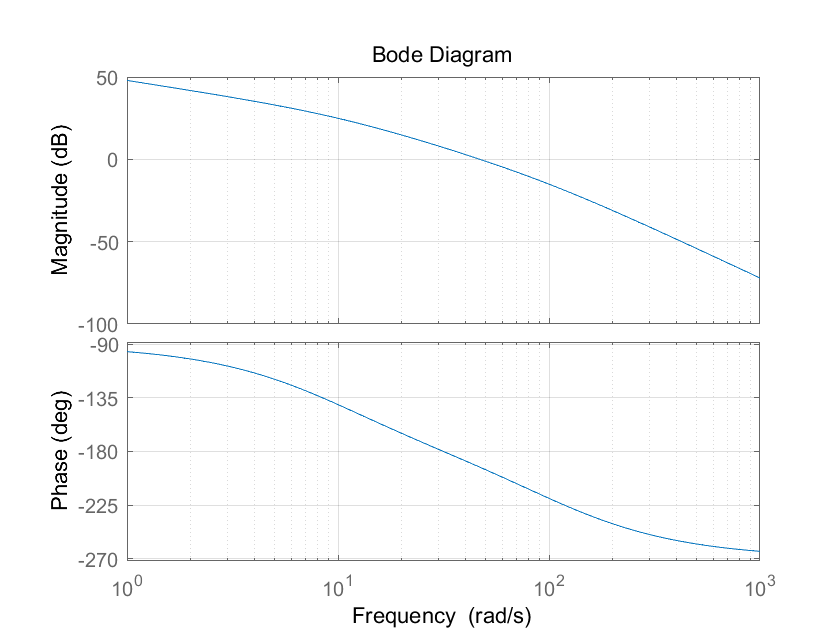


% Calculate where the logspace should be
Min=0;
Max=2;
if isfinite(Wg)
    Min=min([Min,floor(log10(Wg))-1]);
    Max=max([Max,ceil(log10(Wg))+1]);
end
if isfinite(Wc)
    Min=min([Min,floor(log10(Wc))-1]);
    Max=max([Max,ceil(log10(Wc))+1]);
end
[z,p]=tf2zp(Gopen.Numerator{1,1},Gopen.Denominator{1,1});
temp=-real([z,p']);
temp(find(temp==0))=[];
Min=min([Min,floor(log10(temp)-1)]);
Max=max([Max,ceil(log10(temp)+1)]);

% Create a list of number with 100 numbers 
% arrange evenly between 10^0 and 10^4 in log space
w=logspace(Min,Max,100);

% Draw the bode chart of the system
bode(Gopen,w);
grid on;


fprintf('The ampitude margin of the system is %f dB\n', 20*log10(Am));

The ampitude margin of the system is -7.130946 dB


fprintf('\tThe cutoff frequency is %f rad/s\n', Wc);

	The cutoff frequency is 47.040007 rad/s


fprintf('The phase margin of the system is %f degrees\n', Pm);

The phase margin of the system is -13.190737 degrees


fprintf('\tThe traverse frequency is %f rad/s\n', Wg);

	The traverse frequency is 31.622777 rad/s
